% Define the size of the random matrix (e.g., a 4x4 matrix)
n = 100;
p = [10, 100, 1000, 2000];
l = 0.1;
I_n = eye(n);
t_p = [];
t_n = [];

% Generate a random matrix of integers between 1 and 10
for i = 1:length(p)   
    I_p = eye(p(i));
    A = randi([1, 100], n, p(i));
    tic;
    B = inv(A'*A + l .* I_p) * A';
    t_p(i) = toc;
    tic;
    C = A'*inv(A*A' + l * I_n);
    t_n(i) = toc;
end

t_p = 1000 * t_p;
t_n = 1000 * t_n;
disp("t_p: ")

t_p: 


disp(t_p);

    0.8866    0.4024   34.2900  158.3368



disp("t_n: ")

t_n: 


disp(t_n);

    0.9951    0.3015    1.0300    1.4470



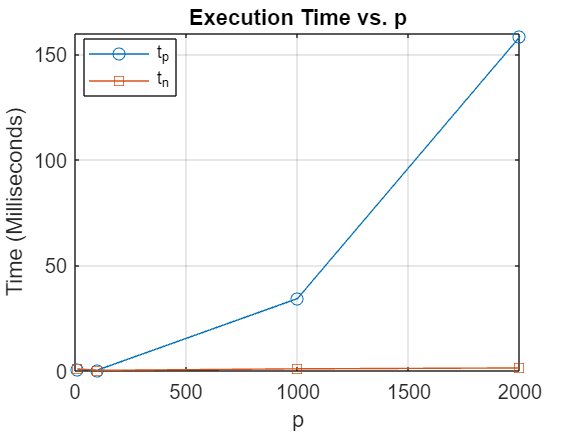


% Create a plot
figure;
plot(p, t_p, '-o', 'DisplayName', 't_p');
hold on;
plot(p, t_n, '-s', 'DisplayName', 't_n');
xlabel('p');
ylabel('Time (Milliseconds)');
title('Execution Time vs. p');
legend('Location', 'Best');
grid on;
hold off;

We can see that the execution time tn is co9nsiderably less than tp. So, this form should be preferred for solving a regressor with large number of samples.